### Circuito Linea de Tranmision

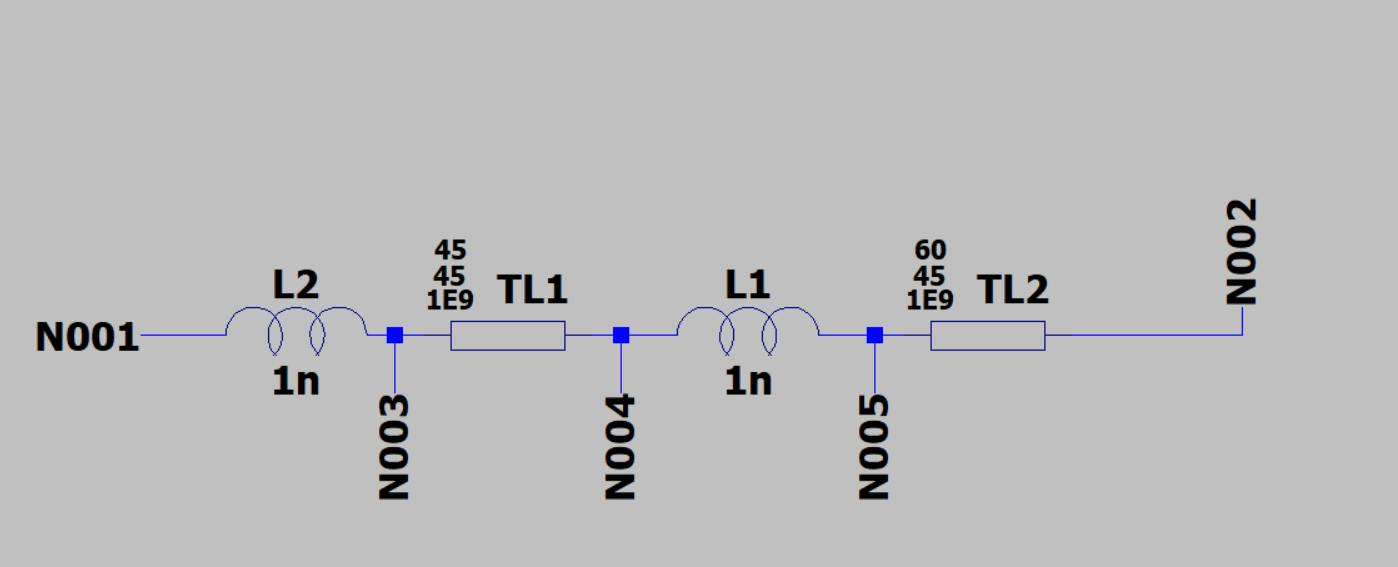

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\LineaTransmision.net';
netlistCell=Netlist2CellArray(netlist_TLfile);

% Metodo Objeto Circuito Matlab
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 60
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


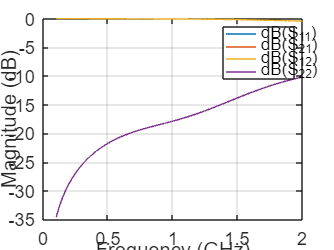

rfplot(SMatlab4);


% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nuevo_Netlist = 8×7 cell array
    {'L1'   }    {'N004'}    {'N005'}    {'L'    }    {[1.0000e-09]}    {[     0]}    {[         0]}
    {'L2'   }    {'N001'}    {'N003'}    {'L'    }    {[1.0000e-09]}    {[     0]}    {[         0]}
    {'TL_Y1'}    {'N003'}    {'N004'}    {'TL_Y1'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y2'}    {'N003'}    {'0'   }    {'TL_Y2'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y3'}    {'N004'}    {'0'   }    {'TL_Y3'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y1'}    {'N005'}    {'N002'}    {'TL_Y1'}    {[        60]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y2'}    {'N005'}    {'0'   }    {'TL_Y2'}    {[        60]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y3'}    {'N002'}    {'0'   }    {'TL_Y3'}    {[        60]}    {[0.7854]}    {[1.0000e+09]}


Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);

Matriz_S=z2s(Matriz_Z,50);

freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


ZMatlab4=s2z(SMatlab4.Parameters,50);
% ----- INICIO----------
